clear
close all
%---setting
expri='ens02';   member=1:10;    lev=10:20;  
%year='2007'; mon='06'; date='01';
year='2018'; mon='06'; date='22';  hr=1:8;  minu='00';
dirmem='pert'; infilenam='wrfout';  dom='01';

indir=['E:/wrfout/expri_ens200323/',expri];
outdir='E:/figures/expri191009/';
titnam='KE spectral';   fignam=[expri,'_KE-sptrl_'];

tic
%dx=1000; dy=1000;

nti=0;    
for ti=hr
  nti=nti+1;
  nmi=0;
  s_hr=num2str(ti,'%.2d');  % start time string
  % ensemble mean
  infile=[indir,'/mean/wrfmean_d',dom,'_',year,'-',mon,'-',date,'_',s_hr,'%3A',minu,'%3A00'];
    u.stag = ncread(infile,'U');u.stag=double(u.stag);
    v.stag = ncread(infile,'V');v.stag=double(v.stag);
    %---
    u.mean=(u.stag(1:end-1,:,:)+u.stag(2:end,:,:)).*0.5;
    v.mean=(v.stag(:,1:end-1,:)+v.stag(:,2:end,:)).*0.5;
  
  
  for mi=member
    nmi=nmi+1;
    %---set filename---    
    nen=num2str(mi,'%.2d');
    infile=[indir,'/',dirmem,nen,'/',infilenam,'_d',dom,'_',year,'-',mon,'-',date,'_',s_hr,'%3A',minu,'%3A00'];
    %------read netcdf data--------
    u.stag = ncread(infile,'U');u.stag=double(u.stag);
    v.stag = ncread(infile,'V');v.stag=double(v.stag);
    %---
    %u.unstag=(u.stag(1:end-1,:,:)+u.stag(2:end,:,:)).*0.5;
    %v.unstag=(v.stag(:,1:end-1,:)+v.stag(:,2:end,:)).*0.5;
    u.pert=(u.stag(1:end-1,:,:)+u.stag(2:end,:,:)).*0.5 - u.mean;
    v.pert=(v.stag(:,1:end-1,:)+v.stag(:,2:end,:)).*0.5 - v.mean;
    
    %---start calculating---
    if nti==1 && nmi==1
      [nx, ny, ~]=size(u.mean); 
      %Lx=dx*nx;  Ly=dy*ny;
      a=repmat(1:max(nx,ny),max(nx,ny),1);
      b=repmat((1:max(nx,ny))',1,max(nx,ny));
      nk=(a.^2+b.^2).^0.5;
      nk2=round(nk(1:nx/2-1,1:ny/2-1));   % !! 算好一個nk矩陣，直接四捨五入!  
      
      KE_khm=zeros(max(nx,ny)/2-1,length(hr));   %KE_kh of different time
    end
  
    %---2D fft for different levels
    KE=zeros(nx/2-1,ny/2-1);  
    for lvi=lev
      u.fft=fft2(u.pert(:,:,lvi))/(nx*ny);
      v.fft=fft2(v.pert(:,:,lvi))/(nx*ny);
      %---calculate KE (power of the FFT)---
      KE(:,:)=KE(:,:)+(abs(u.fft(2:nx/2,2:ny/2))+abs(v.fft(2:nx/2,2:ny/2)))/length(lev);  %2-D low level mean
    end
    %----
    if nmi==1
      KE_kh=zeros(max(nx,ny)/2-1,length(member));  % KE_Kh of each member, reset to zero for each time step
    end
    for ki=1:max(nx,ny)/2-1   
      KE_kh(ki,mi)=sum(KE(nk2==ki));   % sum of different kx, ky to kh bin, for each member
    end
  end  %member
  KE_khm(:,nti)=mean(KE_kh,2);   %ensemble mean
end  %ti
toc

経過時間は 9.811977 秒です。


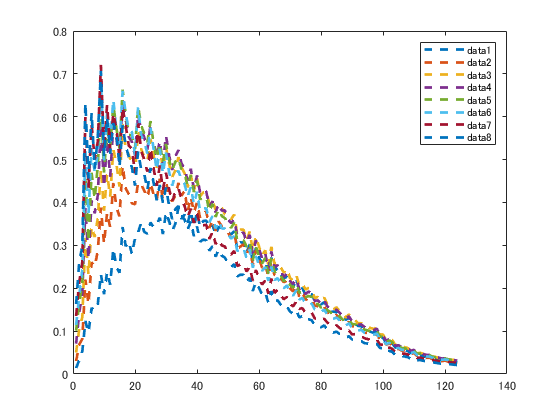

figure 
plot(KE_khm,'LineWidth',2,'LineStyle','--')
legend